# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 11-Aug-2024 13:33:12

## Set up the Import Options and import the data

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet and range
opts.Sheet = "heart";
opts.DataRange = "A2:L919";

% Specify column names and types
opts.VariableNames = ["Age", "Sex", "ChestPainType", "RestingBP", "Cholesterol", "FastingBS", "RestingECG", "MaxHR", "ExerciseAngina", "Oldpeak", "ST_Slope", "HeartDisease"];
opts.VariableTypes = ["double", "categorical", "categorical", "double", "double", "double", "categorical", "double", "categorical", "double", "categorical", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Sex", "ChestPainType", "RestingECG", "ExerciseAngina", "ST_Slope"], "EmptyFieldRule", "auto");

% Import the data
heart = readtable("C:\Users\john\OneDrive\Documents\MATLAB\heart.xlsx", opts, "UseExcel", false)

heart = 918×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N     

## Clear temporary variables

clear opts

### Using indexing to select data

Filtering for only parts of our data for analysis is a very common task in data science. We explored indexing of 

vectors and matrices in chapter 2. We can apply the same principles to table objects. Below, we filter only for 

the first row (all columns) by using indexing. The colon symbol : is shorthand for indicating that we want all (in 

this case

s all the columns). Remember that indexing is in the form row, column.

% Show the data for the first subject
heart(1,:)

ans = 1×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N              0          Up            0      


% The head function is used to display the first n rows of data. Below, we view the first 5 rows.
% Show the data for the first 5 subjects
head(heart,5)

    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N               1        Fl

% The head function is used to display the first n rows of data. Below, we view the first 5 rows.
% Show the data for the first 5 subjects
head(heart,5)

    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N               1        Fl

% The tail function return the last rows.
% Show data for last 5 subjects
tail(heart,5)

    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    45      M          TA             110           264            0          Normal       132           N             1.2        Flat           1      
    68      M          ASY            144           193            1          Normal       141           N             3.4        Fl

% Next we filter for rows 1 and 3 and all the columns.
% Show rows 1 and 3
heart([1 3],:)

ans = 2×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N              0          Up            0      
    37      M          ATA            130           283            0          ST            98           N         

% We can use the names of the columns instead of their indices.
% The names of the columns are passed as a cell array.
% Select only the Age and Sex variables
heart(:,{'Age','Sex'})

ans = 918×2 table
    Age    Sex
    ___    ___

    40      M 
    49      F 
    37      M 
    48      F 
    54      M 
    39      M 
    45      F 
    54      M 
    37      M 
    48      F 
    37      F 
    58      M 
    39      M 
    49      M 
    42      F 
    54      F 


## Data filtering by condition

% Other than indexing, we can also filter by condition. A condition returns either a true or a false value. 
% We use this fact to return only observations that return as value of true. Below,
% we return only observations (with all columns selected) by filtering the Age column for values in excess of 50.
% Filter only those older than 50
heart(heart.Age > 50,:)

ans = 602×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    54      M          NAP            150           195            0          Normal       122           N               0        Up             0      
    54      M          ATA            110           208            0          Normal       142           N       

% Next we filter only for females (encoded as F in the Sex column).
% Filter only female subjects
heart(heart.Sex == "F",:)

ans = 193×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    49      F          NAP            160           180            0          Normal       156           N               1        Flat           1      
    48      F          ASY            138           214            0          Normal       108           Y       

% Filtering on more than one condition is achieved using logical and. The symbol for this is &. Below we filter for 
% all subjects older than 50 who are female. Note that both conditions must be met.
% Filter females older than 50
heart(heart.Age > 50 & heart.Sex == "F",:)

ans = 115×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    54      F          ATA            120           273            0          Normal       150           N             1.5        Flat           0      
    53      F          ATA            113           468            0          Normal       127           N       

% Using logical or to filter values whenever any condition is met. Below we filter for subjects older than 50 or who 
% are female, using the | symbol. We need only one of the condition to be true for inclusion in the filtering.
% Filter females or those older than 50
heart(heart.Age > 50 | heart.Sex == "F",:)

ans = 680×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    49      F          NAP            160           180            0          Normal       156           N               1        Flat           1      
    48      F          ASY            138           214            0          Normal       108           Y       

## Change variable names

It is often required to rename variables. The renamevars function is used to achieve this. Below we change 

the RestingECG column name to the Resting_ECG.

% Change RestingECG to Resting_ECG
heart = renamevars(heart,["RestingECG"],["Resting_ECG"])

heart = 918×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    Resting_ECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    ___________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal        172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal        156           N 

## Add new column based on values of another

Adding new column is a task that is often required in data science. We can add any values to a new column. 

It is most useful, though, to base the values on calculations performed on the values in other columns. Below, 

we convert the units of the Cholesterol column to mmol/L. We also use the round function to round off the 

calculated values to two decimal places.

% Add a new column named Cholesterol_mmol
heart.Cholesterol_mmol = round(heart.Cholesterol ./ 38.67,2)

heart = 918×14 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    Resting_ECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol    HeartDiseaseClass
    ___    ___    _____________    _________    ___________    _________    ___________    _____    ______________    _______    ________    ____________    ________________    _________________

    40      M          ATA            140           289            0          Normal        172           N     

## Change the values of observations in a column based on conditions

The values in a new column can also be created based on conditions applied to the values of another column. 

Below we add a new column called HeartDiseaseClass and assign the values of the HeartDisease

column to the new column.

% Add a new column called HeartDiseaseClass as a copy of the HeartDisease
% variable
heart.HeartDiseaseClass = heart.HeartDisease

heart = 918×14 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    Resting_ECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol    HeartDiseaseClass
    ___    ___    _____________    _________    ___________    _________    ___________    _____    ______________    _______    ________    ____________    ________________    _________________

    40      M          ATA            140           289            0          Normal        172           N     

% Next, we use the ismember function to filter for rows with a 0 in the new HeartDisease class and replace 
% them with the value No.
% Change the values in the new column to "No" if the value is 0
heart.HeartDiseaseClass(ismember(heart.HeartDiseaseClass, ["0"])) = "No"


% We do the same for those with heart disease.
% Change the values in the new column to "Yes" if the value is 1
heart.HeartDiseaseClass(ismember(heart.HeartDiseaseClass, ["1"])) = "Yes"


## Change numerical variable to nominal variable

Categorizing a numerical variable is another common task in data science. Below, we create three classes 

based on the Age column by using the discretize function and setting the intervals as left-closed right-open 

intervals.

% Add a new column to the data table called AgeClass
% Let observation be "Group A" if Age observation is in interval [0,50)
% Let observation be "Group B" if Age observation is in interval [50,75)
% Let observation be "Group C" if Age observation is in interval [75,100)
heart.AgeClass = discretize(heart.Age, [0 50 75 100], 'categorical', ["Group A", "Group B", "Group C"])

heart = 918×13 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    AgeClass
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________    ________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0          Group A 
    49      F          NAP            160

## Working with dates and times

Working with dates and times is essential and sometimes very difficult. Most difficulty stems from the data 

capture in a spreadsheet of database file. The problems that we face with dates and times can be avoided 

by proper data capture in a consistent format and not using formatting built into spreadsheet and database 

programs. In this section, we use MATLAB to generate dates and times.

% Add day as a string
datetime('June 18, 2024')

ans = datetime
   18-Jun-2024



% Current day and time
dt = datetime("now")

dt = datetime
   11-Aug-2024 14:55:23



% Year
year(dt)

ans = 2024


dt.Year

ans = 2024


% Month number
month(dt)

ans = 8


%Month name
month(dt,'name')

ans = 1×1 cell array
    {'August'}



% Day
day(dt)

ans = 11


% Day of the week
day(dt,'dayofweek')

ans = 1


% Long day name
day(dt,'name')

ans = 1×1 cell array
    {'Sunday'}



[y,m,d] = ymd(dt)

y = 2024

m = 8

d = 11


years = randi(24,20,1) + 2000

years =         2021
        2015
        2009
        2013
        2010
        2002
        2006
        2003
        2005
        2006


months = randi(12,20,1)

months =     10
     5
     3
     5
     2
     2
    12
    12
     7
     1



days = randi(28,20,1)

days =     16
     9
    21
     6
    20
     6
    11
    18
    22
     3



dates = datetime([years months days],"Format","uuuu-MM-dd")

dates = 20×1 datetime array
   2021-10-16
   2015-05-09
   2009-03-21
   2013-05-06
   2010-02-20
   2002-02-06
   2006-12-11
   2003-12-18
   2005-07-22
   2006-01-03
   2011-03-27
   2002-05-22
   2022-10-14
   2023-01-13
   2012-01-13
   2012-03-09
   2009-08-15
   2022-09-15
   2009-08-23
   2003-06-23



day(dates,'name')

ans = 20×1 cell array
    {'Saturday' }
    {'Saturday' }
    {'Saturday' }
    {'Monday'   }
    {'Saturday' }
    {'Wednesday'}
    {'Monday'   }
    {'Thursday' }
    {'Friday'   }
    {'Tuesday'  }
    {'Sunday'   }
    {'Wednesday'}
    {'Friday'   }
    {'Friday'   }
    {'Friday'   }
    {'Friday'   }
    {'Saturday' }
    {'Thursday' }
    {'Sunday'   }
    {'Monday'   }



% Create a logical array to hold all the weekend dates
idx = isweekend(dates)% Display the weekend dates

idx = 20×1 logical array
   1
   1
   1
   0
   1
   0
   0
   0
   0
   0


dates(idx)

ans = 7×1 datetime array
   2021-10-16
   2015-05-09
   2009-03-21
   2010-02-20
   2011-03-27
   2009-08-15
   2009-08-23


% Next we import a spreadsheet file that contains a date column. This is done from the HOME tab.
% Call file from Workspace
DateData

Unrecognized function or variable 'DateData'.

% Compute group summary
frequencyTable = groupsummary(DateData,"Date","monthname")

Unrecognized function or variable 'DateData'.


% Create bar of selected data
h3 = bar(frequencyTable.monthname_Date,frequencyTable.GroupCount,"DisplayName","GroupCount");
% Add xlabel, ylabel, title, and legend
xlabel("monthname_Date")
ylabel("GroupCount")
title("GroupCount vs. monthname_Date")
legend


## Missing data

Missing data can occur commonly in data sets. Missing data refers to the absence of data points or values in 

a dataset where they were expected or should have been recorded. This can occur for various reasons such 

as non-response in surveys, data collection errors, or loss of data during storage. There are different types of 

missingness.

1. Missing Completely at Random (MCAR): Missing data is considered MCAR if the probability of a data point 

being missing is completely independent of any observed or unobserved data in the dataset. In other words, the 

missingness is unrelated to the values of any variables. For instance, if survey responses are missing purely 

due to random technical errors, the data is MCAR

2. Missing at Random (MAR): Missing data is considered MAR if the probability of a data point being missing 

is related to some of the observed data but not the missing data itself. That means the missingness can 

be explained by other measured variables in the dataset. For example, if older individuals are less likely to 

answer a particular survey question, but this tendency is consistent across all questions, the data is MAR if age 

information is recorded

3. Missing Not at Random (MNAR): Missing data is considered MNAR if the probability of a data point being 

missing is related to the value of the missing data itself. This means that the missingness is systematically 

related to the unobserved value. For instance, if people with higher incomes are less likely to report their 

income, the data is MNAR.

In this section we only explore the use of the Clean Missing Data app. First we note that the nan keyword, 

which is short for not a number is used to indicate missing data.

% Use the nan keyword
nan

ans = NaN

% We create a column vector of random integers and then overwrite the values at indices , and 14 with the 
% nan keyword.
% Create a column vector of 20 random integers assigned to the variable
% array
array = randi(10,20,1)+20

array =     28
    23
    26
    27
    29
    30
    26
    22
    22
    23


% Overwrite observations 3, 11, and 14 with missing data
array([3 11 14]) = nan

array =     28
    23
   NaN
    27
    29
    30
    26
    22
    22
    23


% We cannot calculate statistics such as the mean with this vector as the values held at indices , and 14 are 
% unknown.
% Calculate the mean
mean(array)

ans = NaN

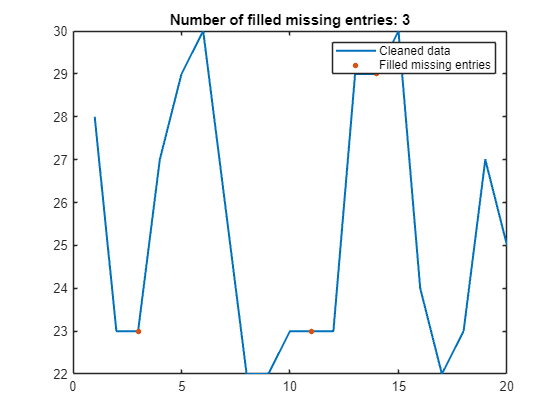

% The simplest task is to remove observations with missing data. This might be a problem when there are many 
% missing observations. Instead, the Clean Missing Data app can be used to impute the missing data.
% Fill missing data
[cleanedArray,missingIndices] = fillmissing(array,"previous");
% Display results
figure
% Plot cleaned data
plot(cleanedArray,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","Cleaned data")
hold on
% Plot filled missing entries
plot(find(missingIndices),cleanedArray(missingIndices),".","MarkerSize",12, "SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))
hold off
legend

% RED dots show the missing data !!!!!!!!!!!!!!!!!!
% Tasks option - search - missing data - clean - ----
% - can change -Specify Method - 

clear missingIndices
% The mean can now be calculated.
% Calculate the mean
mean(cleanedArray)

ans = 25.4000